%% Visualization for the data:
clc, clearvars, close all
addpath('data/')
healthy = readmatrix("data/data.xlsx",'Sheet','No.2WT'); % Healthy turbine
WT3 = readmatrix("data/data.xlsx",'Sheet','No.3');
faulty14 = readmatrix("data/data.xlsx",'Sheet','No.14WT');
faulty39 = readmatrix("data/data.xlsx",'Sheet','No.39WT');


WT3 data seems to not be in any consistent order compared to other datasets, and also has extra columns compared to them, so we are not using the data in this analysis. Dropping the last column from the healthy, because it is an extra quality variable and is not found from the remaining datasets.

healthy(:,end) = [];
labels = string(1:size(healthy, 2))

labels = 1×27 string array
    "1"    "2"    "3"    "4"    "5"    "6"    "7"    "8"    "9"    "10"    "11"    "12"    "13"    "14"    "15"    "16"    "17"    "18"    "19"    "20"    "21"    "22"    "23"    "24"    "25"    "26"    "27"


Removing the header row

healthy(1,:) = [];
faulty14(1,:) = [];
faulty39(1,:) = [];

% Normalized datas:
norm_healthy = zscore(healthy)

norm_healthy =     1.1037   -1.3095    0.1974   -0.1397    0.0355    0.0238    0.0400    0.0515   -1.9389    0.0266    0.0619         0   -0.0454    0.4723         0   -1.4831    1.9825    0.3611    0.8302    0.4967    0.0484    1.6582   -1.6475    0.4175    1.9791   -0.7017   -0.5383
    0.3985   -0.4295    0.1974   -0.1103    0.0089    0.0316    0.0400    0.0489   -1.9338   -0.0011    0.0314         0   -0.0454   -0.7802         0   -1.4836    1.9825    0.5005    0.8302    0.4967   -0.0424    1.6582    0.4454   -0.0410    1.9791   -0.7017   -0.5498
    1.8090   -1.1628    0.1974   -0.1220    0.0013    0.0238    0.0400    0.0408   -1.9338   -0.0063    0.0134         0   -0.0454   -0.7802         0   -1.4836    1.9825    0.3611    0.8302    0.5860   -0.0424    1.6582   -0.0900    0.7723    1.9791   -0.7017   -0.5383
   -1.2472    0.8904    0.1974   -0.1103   -0.0337    0.0238    0.0592    0.0515   -1.9338   -0.0268   -0.0080         0   -0.0454    1.0985         0   -1.4831    1.9825  

norm_faulty14 = zscore(faulty14)

norm_faulty14 =     4.4184   -0.0425    1.1292    1.1566   -0.9337    1.6889    1.7076    1.7142       NaN   -0.9299   -0.6779   -0.9563    0.9248    0.0896    0.0382   -0.9443    1.2345    0.1663    0.0032    0.9181    0.9176    1.0176   -1.3358    1.2526    1.4082    2.2646    2.8613
   -6.0528   -0.7260    1.1292    1.1561   -0.9337    1.6834    1.6993    1.7087       NaN   -0.9299   -0.7504   -0.9563    0.9594    0.0896    0.0382   -0.9443    1.2320    0.1892    0.0032    0.9153    0.9203    1.0176   -1.6632    1.9935    1.4082    2.2242    2.7703
    2.8477    0.6410    1.1292    1.1556   -0.9337    1.6777    1.6963    1.7028       NaN   -0.9299   -0.7499   -0.9563    0.9626    0.0896    0.0382   -0.9443    1.2320    0.2007   -0.0020    0.9181    0.9181    1.0176   -1.7889    1.6671    1.4082    2.1815    2.6805
    2.3241   -1.0678    1.1292    1.1519   -0.9337    1.6678    1.6921    1.6971       NaN   -0.9299   -0.7532   -0.9563    0.9626    0.0896    0.0382   -0.9443    1.2320 

norm_faulty39 = zscore(faulty39)

norm_faulty39 =     4.7074    0.1536    1.9582    2.2688   -1.3575    2.3857    2.2824    2.2056   -1.3225   -1.3587   -1.3316   -1.4098    1.3635    0.3761   -1.4115    1.3861   -0.0331    0.0351    0.0433    1.6186    1.7005    2.6590   -1.2558    1.9482   -1.4132    2.3249    3.3960
   -4.0486   -0.9729    1.9529    2.2688   -1.3575    2.3685    2.2824    2.1933   -1.3225   -1.3587   -1.3766   -1.4098    1.4064    0.3761   -1.4115    1.3861   -0.0331    0.0841    0.0283    1.6284    1.7005    2.6590    1.2076    1.8152   -1.4132    2.2972    3.3249
    1.4552   -0.1682    1.9582    2.2688   -1.3575    2.3492    2.2824    2.1685   -1.3225   -1.3587   -1.4076   -1.4098    1.4121    0.3761   -1.4115    1.3861   -0.0331    0.1331   -0.0017    1.6264    1.7005    2.6590    0.6463    1.2187   -1.4132    2.2694    3.2746
    2.2057    0.7973    1.9451    2.2688   -1.3575    2.3354    2.2824    2.1685   -1.3225   -1.3587   -1.4044   -1.4098    1.4123    0.3761   -1.4115    1.3861   -0.0331 

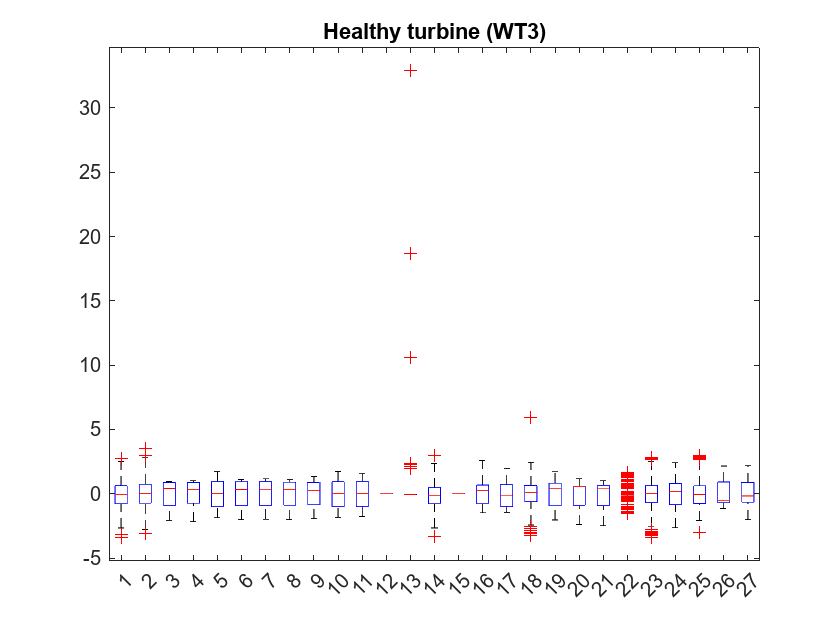


% Corresponding box plots:
boxplot(norm_healthy)
title('Healthy turbine (WT3)')

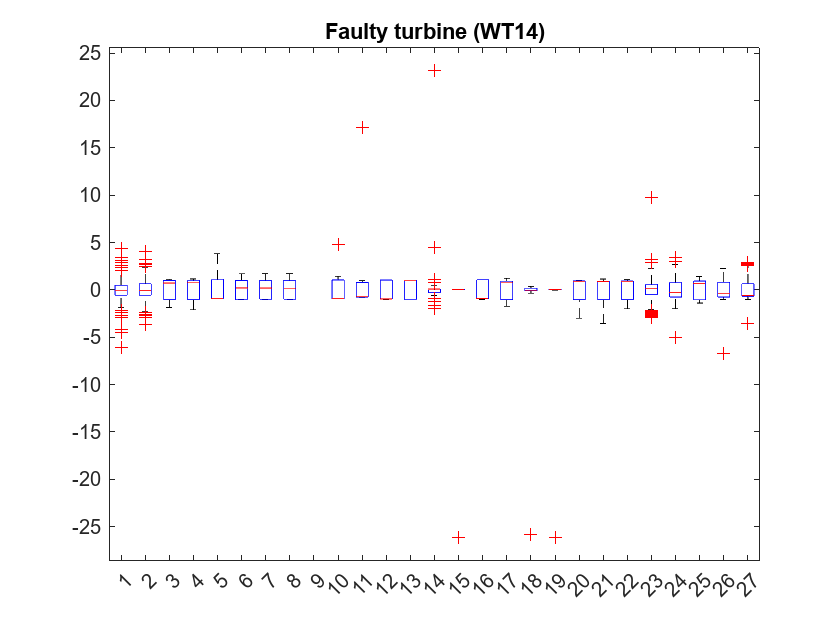

figure
boxplot(norm_faulty14)
title('Faulty turbine (WT14)')

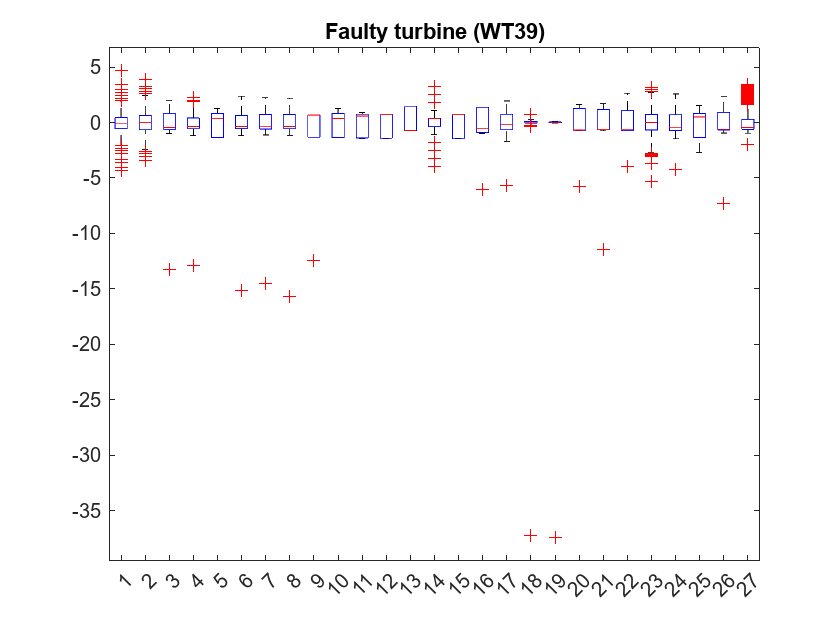

figure
boxplot(norm_faulty39)
title('Faulty turbine (WT39)')

## Missing values

Checking the missing values and filling with the previous one


missing_2 = sum(isnan(healthy))

missing_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


missing_14 = sum(isnan(faulty14))

missing_14 =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ROWBYROW = 2;
faulty14 = fillmissing(faulty14,'previous',ROWBYROW);

missing_39 = sum(isnan(faulty39))

missing_39 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Data Summary

mean_2 = mean(healthy);
mean_14 = mean(healthy);
mean_39 = mean(healthy);

min_2 = min(healthy);
min_14 = min(faulty14);
min_39 = min(faulty39);

max_2 = max(healthy);
max_14 = max(faulty14);
max_39 = max(faulty39);

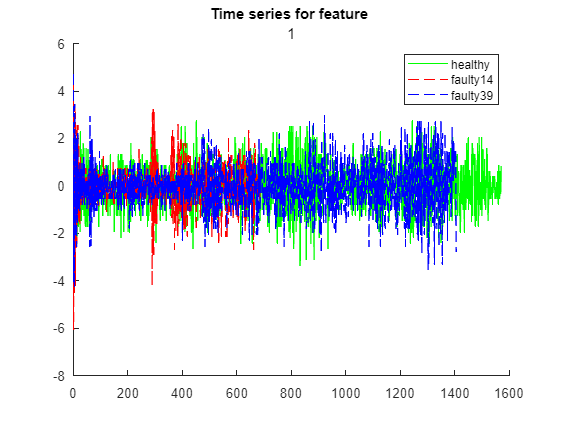

plotdata(norm_healthy,norm_faulty14,norm_faulty39,1)

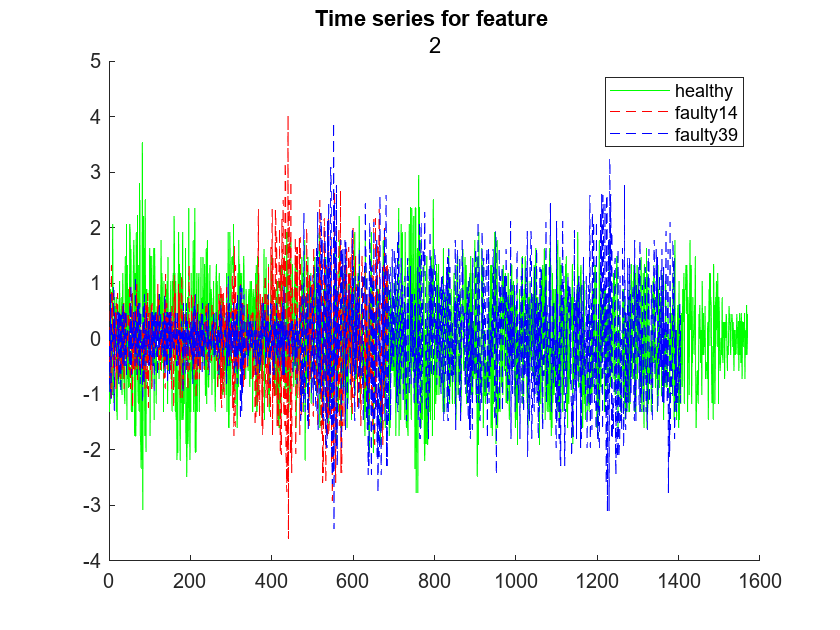


plotdata(norm_healthy,norm_faulty14,norm_faulty39,2)

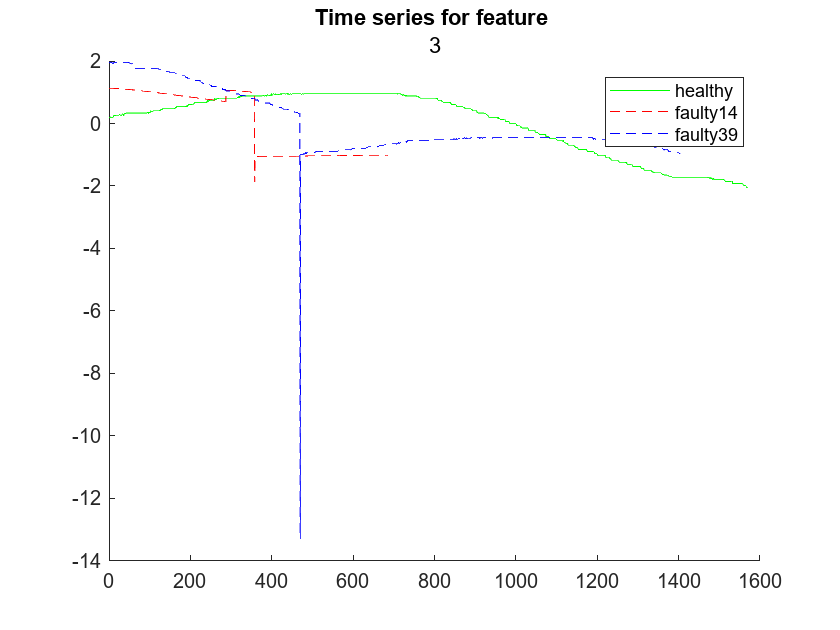


plotdata(norm_healthy,norm_faulty14,norm_faulty39,3)

## Data splitting

Splitting the data into calibration, validation and test sets

CALIBRATION_SIZE = 0.7;
VALIDATION_SIZE = 0.2;
TEST_SIZE = 0.1;

n_healthy_calib = floor(size(norm_healthy,1)*CALIBRATION_SIZE);
n_healthy_valid = floor(size(norm_healthy,1)*VALIDATION_SIZE);
n_healthy_test = size(norm_healthy,1) - (n_healthy_calib + n_healthy_valid);

norm_healthy_calib = norm_healthy(1:n_healthy_calib,:);
norm_healthy_valid = norm_healthy(1:n_healthy_valid,:);
norm_healthy_test = norm_healthy(1:n_healthy_test,:);

## Correlation plot

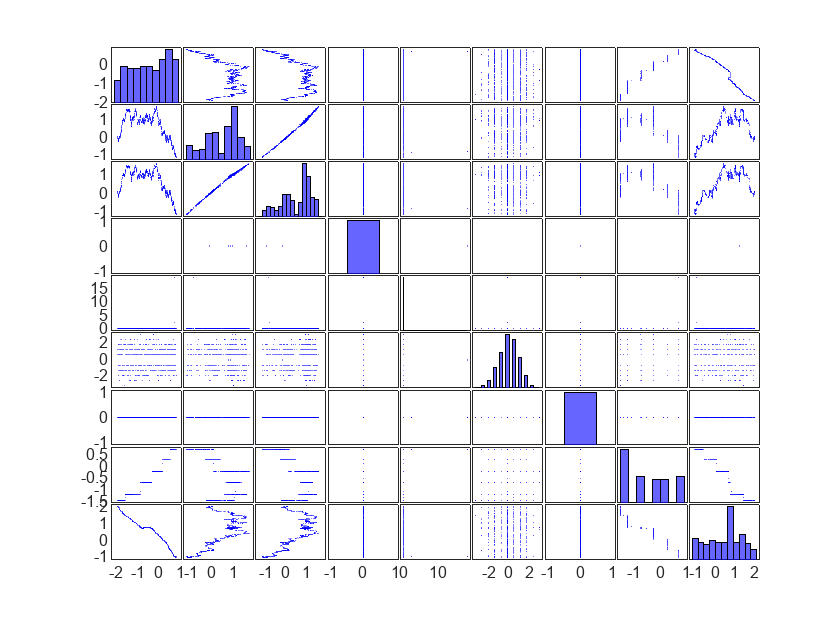

figure
gplotmatrix(norm_healthy_calib(:,1:8), [])
figure
gplotmatrix(norm_healthy_calib(:,9:17), [])

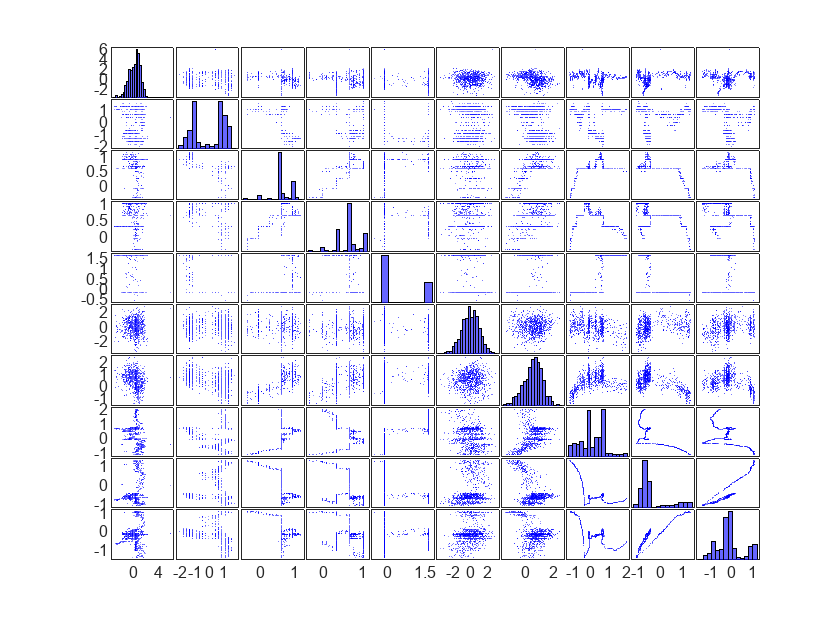

figure
gplotmatrix(norm_healthy_calib(:,18:27), [])

## PCA


model(1).X = norm_healthy_calib; %Pretreat data
[model(1).P, model(1).T, model(1).latent, model(1).T2all, model(1).explVar, model(1).mu] = pca(model(1).X);

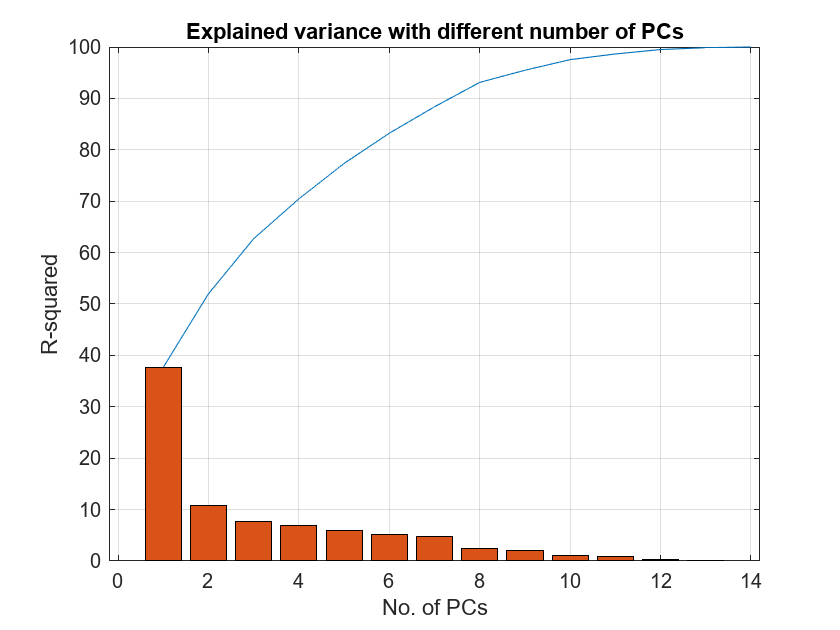

figure; 
explVar = 100 * cumsum(model(1).latent(1:14)) / sum(model(1).latent(1:14));
changeAmount(1) = explVar(1);
for i = 2:length(explVar)-1
    changeAmount(i) = explVar(i+1)-explVar(i);
end
plot(1:14, explVar); hold on;
bar(changeAmount)
title('Explained variance with different number of PCs'); 
xlabel("No. of PCs"); ylabel("R-squared"); grid on;

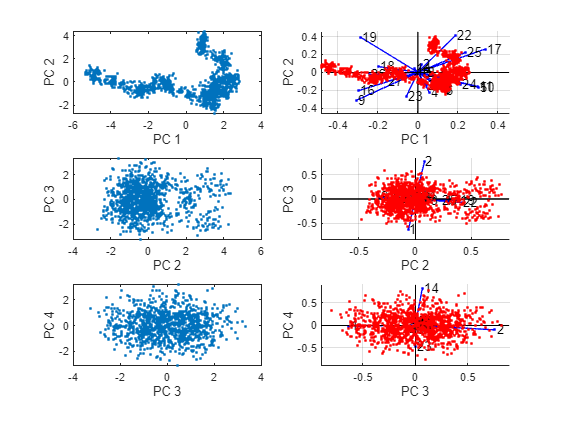

figure; 
ii = 1;

for i = 4:6

    subplot(3,2,ii);
    gscatter(model(1).T(:,i), model(1).T(:,i+1));
    text1 = "PC " + string(i);
    text2 = "PC " + string(i+1);
    xlabel(text1);
    ylabel(text2);
    ii      = ii + 1;

    subplot(3, 2, ii);
    biplot(model(1).P(:,i:(i+1)), 'Scores', model(1).T(:,i:(i+1)), 'VarLabels', labels);
    xlabel(text1);
    ylabel(text2);
    ii = ii + 1;
end

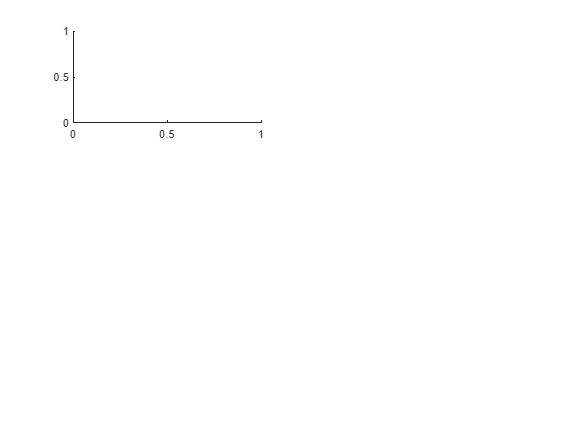

Error using bar
Not enough input arguments.

%% Loadings
figure;
ii = 1;
for i = 4:6
    subplot(3,2,ii);
    bar(labels,model(1).P(:,i)); %Loadings bar plot
    text = "Loadings for PC " + string(i);
    title(text);
    ii = ii + 1;

    subplot(3,2,ii);
    gscatter(1:length(model(1).T(:,i)), model(1).T(:,i));
%     xticklabels(inputs);
    text = "Scores for " + string(i);
    title(text);
    xlabel("observation no.");
    ylabel("Score value");
    ii = ii + 1;
end

function [H] = plotdata(healthy,faulty14,faulty39,column)
    figure
    hold on
    plot(healthy(:,column),'g-')
    plot(faulty14(:,column),'r--')
    plot(faulty39(:,column),'b--')
    title('Time series for feature ',column)
    legend('healthy','faulty14','faulty39')
end
